clear all;

w_d = 5;
zeta = 0.7;
w_n = w_d / sqrt(1 - zeta^2);
T = 0.2;
K_v = 0.25

K_v = 0.2500


z1 = exp(-zeta * w_n * T) * (cos(w_d * T) + 1j * sin(w_d * T))

z1 = 0.2027 + 0.3158i

z2 = exp(-zeta * w_n * T) * (cos(w_d * T) - 1j * sin(w_d * T))

z2 = 0.2027 - 0.3158i


syms s;

poly_ = simplify((s - z1) * (s - z2))

$$poly\_ = s^{2}-\frac{3652269759055579\,s}{9007199254740992}+\frac{22846625192583957903284970060445}{162259276829213363391578010288128}$$

vpa(poly_, 4)

$$ans = s^{2}-0.4055\,s+0.1408$$

c_1 = -2*exp(-zeta*w_n*T)*cos(w_d*T)

c_1 = -0.4055

c_2 = exp(-2*zeta*w_n*T)

c_2 = 0.1408

p_1 = 1 + c_1 + c_2

p_1 = 0.7353

p_2 = 2 + c_1

p_2 = 1.5945

b_1_coef = (p_1 - p_2) 

b_1_coef = -0.8592

b_2_coef = -p_2 

b_2_coef = -1.5945


r_20 = 1 / (T* K_v);
coef_20_res = r_20 * p_1^2

coef_20_res = 10.8139


syms b1 b2

eq1 = b1 + b2 == p_1;
eq2 = -b_1_coef*b1 -b_2_coef*b2 == coef_20_res;

sol = solve([eq1, eq2], [b1, b2]);

b1_val = double(sol.b1)

b1_val = -13.1119

b2_val = double(sol.b2)

b2_val = 13.8472


D_z_1 = -b1_val + c_1

D_z_1 = 12.7064

D_z_0 = -b2_val + c_2

D_z_0 = -13.7064




T_n_z3 = b1_val

T_n_z3 = -13.1119

T_n_z2 = -1.5 * b1_val + b2_val

T_n_z2 = 33.5150

T_n_z1 = 0.5 * b1_val + b2_val * (-1.5)

T_n_z1 = -27.3267

T_n_z0 = b2_val * 0.5

T_n_z0 = 6.9236



T_d_z3 = 0.03 * 1

T_d_z3 = 0.0300

T_d_z2 = 0.03 * 1 * 0.75 + 0.03 * D_z_1

T_d_z2 = 0.4037

T_d_z1 = 0.03 * D_z_1 * 0.75 + 0.03 * 1 * D_z_0

T_d_z1 = -0.1253

T_d_z0 = D_z_0 * 0.03 * 0.75

T_d_z0 = -0.3084

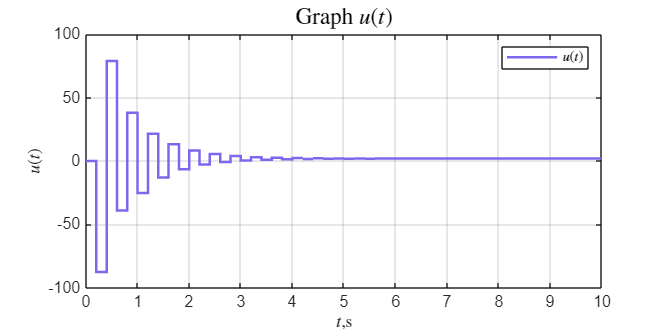


%======================================================
% GRAPHICS
%======================================================

set_param('schem_3/y', 'VariableName', 'y');
set_param('schem_3/u', 'VariableName', 'u');
set_param('schem_3/e', 'VariableName', 'e');


out = sim('schem_3');
y_ = out.y.Data;
t_ = out.y.Time;
u_ = out.u.Data;
tu_ = out.u.Time;
e_ = out.e.Data;
te_ = out.e.Time;

% Построение графика

% Определяем цвета для линий
a_color = '#00FFFF'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(tu_, u_, '-', 'LineWidth', 1.5, 'Color', b_color);

grid on;

title('Graph $u(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$u(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$u(t)$','Interpreter', 'latex')
%ylim([1])
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_4\Discrete_report_4\pic\' ...
    '3_2_u.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

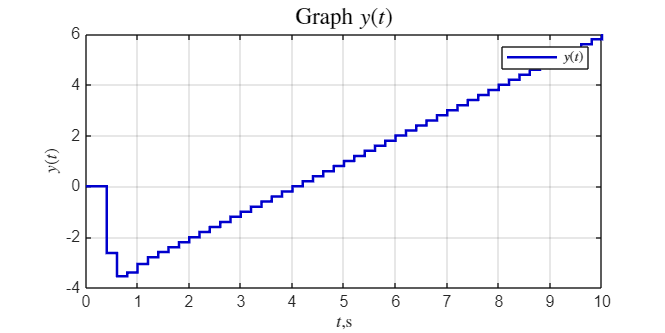



figure('Position', [100 100 800 400]);
stairs(t_, y_, '-', 'LineWidth', 1.5, 'Color', d_color);

grid on;

title('Graph $y(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$y (t)$','Interpreter', 'latex')

hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_4\Discrete_report_4\pic\' ...
    '3_2_y.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

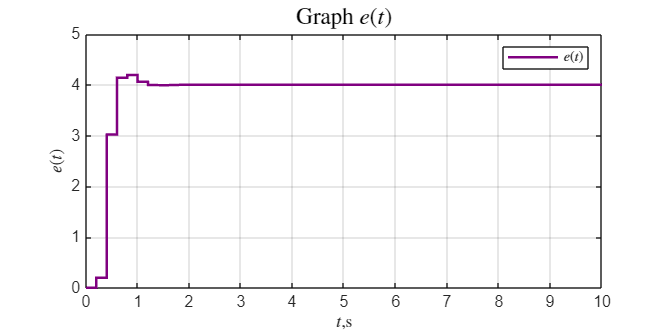


figure('Position', [100 100 800 400]);
stairs(te_, e_, '-', 'LineWidth', 1.5, 'Color', c_color);

grid on;

title('Graph $e(t)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e(t)$','Interpreter', 'latex' );
xlabel('$t$,s', 'Interpreter', 'latex');
legend('$e (t)$','Interpreter', 'latex')

hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_4\Discrete_report_4\pic\' ...
    '3_2_e.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);


%{
syms z
% z = 5
T_num = (b1_val * z + b2_val) * (z^2 -1.5 * z + 0.5)
T_dem = (z^2 + D_z_1 * z + D_z_0) * (0.03 * (z + 0.75))

y = T_num /T_dem 
z =  (T_n_z3 * z^3 + T_n_z2 * z^2 + T_n_z1 * z + T_n_z0) / (T_d_z3 * z^3 + T_d_z2 * z^2 + T_d_z1 * z + T_d_z0)
f = y / z
vpa(f, 4)
%}